# Filtro espectral

clear;
load tseries_test.mat;
[NT,tserie_size] = size(tseries_test);

#### Cargar una serie de tiempo de prueba

Fs = 23;              % Frecuencia de muestra (muestras por unidad de tiempo o espacio)               
T = 1/Fs;             % espacio por muestra    
L = tserie_size;      % Length of signal
t = (0:L-1)*T;        % Time vector

%id = 10;
id =9;
S  = tseries_test(id,:);

#### Agregar huecos de manera artificial aleatoria

% % % %id = 10;
% % % huecos =196;
% % % nhuecos = 0;
% % % Snan = S;
% % % while (nhuecos<huecos)
% % %     x = randi([1 tserie_size]);
% % %     if( ~isnan(Snan(x)) )
% % %         Snan(x)=nan;
% % %         nhuecos=nhuecos+1;
% % %     end
% % % end
% % % 
% % % %%% mostrar la serie original y la serie artifical con huecos
% % % figure;
% % % plot(S);
% % % ylim([0 1]);
% % % xlim([1 tserie_size]);
% % % ylabel('NDVI','FontSize',12);
% % % xlabel('Días','FontSize',12);
% % % hold on; 
% % % plot(Snan);
% % % hold off;
% % % 
% % % mean_snan = mean(Snan,"all","omitnan");
% % % disp("PROMEDIO: "+mean_snan);
% % % Snan( isnan(Snan))=mean_snan;
% % % 
% % % figure;
% % % plot(S);
% % % ylim([0 1]);
% % % xlim([1 tserie_size]);
% % % ylabel('NDVI','FontSize',12);
% % % xlabel('Días','FontSize',12);
% % % hold on; 
% % % plot(Snan);
% % % hold off;


#### Agregar huecos de manera artificial definida

En los años: 2003, 2006, 2008, 2011, 2014, 2015, 2017 2020, 2022

Días: 7, 40, 66, 73, 129, 197, 263, 291, 341, 401, 438

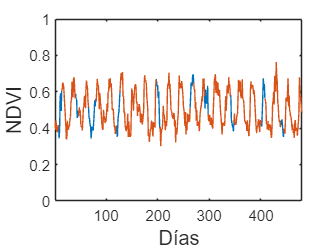

%id = 10;
Snan = S;


tam_huecos =6;
id_huecos= [7 40 66 73 120 197 263 291 341 401 438];
for i=id_huecos
    for j=1:tam_huecos
        Snan(i+j)=nan;
    end
end
Snano = Snan;
for i=id_huecos
    for j=1:tam_huecos
        idp = (i+j):23:tserie_size;
        prom = mean(Snan(idp),"all","omitnan");
        Snan(i+j) = prom;
    end
end



%%% mostrar la serie original y la serie artifical con huecos
figure;
plot(S);
ylim([0 1]);
xlim([1 tserie_size]);
ylabel('NDVI','FontSize',12);
xlabel('Días','FontSize',12);
hold on; 
plot(Snano);
hold off;

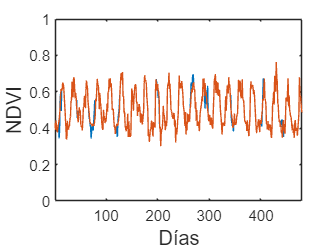


% mean_snan = mean(Snan,"all","omitnan");
% disp("PROMEDIO: "+mean_snan);
% Snan( isnan(Snan))=mean_snan;

figure;
plot(S);
ylim([0 1]);
xlim([1 tserie_size]);
ylabel('NDVI','FontSize',12);
xlabel('Días','FontSize',12);
hold on; 
plot(Snan);
hold off;

## Espectro de amplitud de la serie

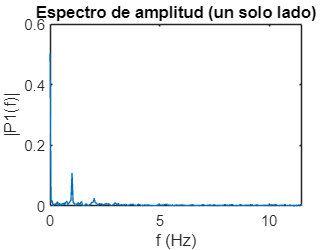

Y = fft(Snan);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure;
plot(f,P1) 
title("Espectro de amplitud (un solo lado)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

## Suavizar mediante Frecuencia mayor amplitud

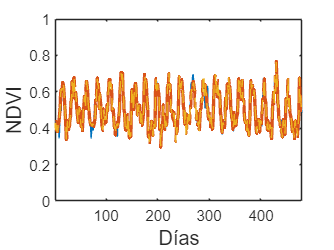

mit = L/2;
Nx = length(S);

rng = 2;
Yf = Y;

Yf(mit-rng+1:mit+rng+1) = 0;

Yfp = abs(Yf);
P2 = abs(Yfp/L);
P1 = P2(1:int16(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

%Ajustrar segunda mitad del espectro
%Yf(length(Yf)+1:Nx) = conj(Yf(Nx-length(Yf)+1:-1:2)); 

% Comparar con filtro Lanczos
%Mejores parametros para el filtro Lanczos
dT = 23;
cf= 1/46;
[Sl,~,~,~,~] = lanczosfilter(Snan,dT,cf,[],'low');  

Sf = real(ifft(Yf));
figure;
plot(S);
ylim([0 1]);
xlim([1 tserie_size]);
ylabel('NDVI','FontSize',12);
xlabel('Días','FontSize',12);
hold on
plot(Sf,LineWidth=2);
%plot(Snano);
plot(Sl,LineStyle="--");
hold off

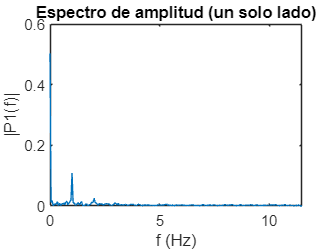


figure;
plot(f,P1) 
title("Espectro de amplitud (un solo lado)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

#### Calcular RMSE MAE CORRELACION Y SESGO

disp("fft");

fft



m_rmse = f_rmse(S,Sf)

m_rmse =    0.021145841360339


m_mae = f_mae(S,Sf)

m_mae =    0.010516785723659


cor = corrcoef(S,Sf);
m_corr = cor(2,1)

m_corr =    0.976859573455365



m_sesgo_s = skewness(S)

m_sesgo_s =    0.296188494192321


m_sesgo_sf =skewness(Sf)

m_sesgo_sf =    0.309010365549204



mdl = fitlm(S,Sf);

m_R2o = mdl.Rsquared.Ordinary

m_R2o =    0.954254626251398


m_R2 = mdl.Rsquared.Adjusted

m_R2 =    0.954158924632677



% Lanczos 

disp("Lanczos");

Lanczos


m_rmse = f_rmse(S,Sl)

m_rmse =    0.123702781844420   0.148033388336047   0.114597712117565   0.143549583989203   0.154016704810425   0.158489073154903   0.129360502862821   0.140478262960249   0.185452181849764   0.146827122139985   0.124327199159881   0.130292635707018   0.097296592779542   0.139827639037994   0.149627692763168   0.175831171861792   0.171102723377303   0.151311288658218   0.118371677773544   0.098486965916118   0.103277739103942   0.134449399215445   0.190422406030181   0.188703185943951   0.115352051805022   0.139539536146309   0.147429318417608   0.136335913826269   0.132318178771320   0.111506208902476   0.104657498665796   0.106114458065609   0.110432588468566   0.180109578172096   0.173501128135777   0.117515762128397   0.191974211381361   0.201635701173569   0.156046675901753   0.114597623146693   0.130225769094016   0.110770557818147   0.110722068694501   0.107898439942560   0.097461721885306   0.103487542701040   0.104171933890944   0.097507043612336   0.097627493391446   0.097009

m_mae = f_mae(S,Sl)

m_mae =    0.094632810579348   0.116836749898131   0.088970258496014   0.112186749898131   0.123253416564798   0.128179666564798   0.098896371921940   0.109084583231464   0.158558833231464   0.115571333231464   0.106218563784034   0.110775595034034   0.083268667639533   0.118253608687728   0.126370260518536   0.150820333435202   0.146183666768536   0.127842343851869   0.101841063784034   0.086919298149750   0.084187523542311   0.103292499898131   0.164246333231464   0.162279666564798   0.089357341829348   0.108149166564798   0.116200083231464   0.105045833231464   0.101405017755274   0.087534216829348   0.084654606875644   0.093232631483083   0.096313325927528   0.155150333435202   0.148518666768536   0.101238392215406   0.167411583435202   0.177758250101869   0.132097083435202   0.099205475548740   0.110724761700701   0.096552492594194   0.096518325927528   0.085964106875644   0.083206167639533   0.084255023542311   0.084486690208977   0.085665127544008   0.083154084306200   0.0834940

cor = corrcoef(S,Sl);
m_corr = cor(2,1)

m_corr =    0.978561954361843



m_sesgo_s = skewness(S)

m_sesgo_s =    0.296188494192321


m_sesgo_sf =skewness(Sl)

m_sesgo_sf =    0.318056659356112



mdl = fitlm(S,Sl);

m_R2o = mdl.Rsquared.Ordinary

m_R2o =    0.957583498524470


m_R2 = mdl.Rsquared.Adjusted

m_R2 =    0.957494761073684
